% Define parameters
Fs = 1e6; % Sampling frequency (1 MHz)
Fc_desired = 104.1e6; % Frequency of the desired station (104.1 MHz)
Fc_interfere_low = 103.9e6; % Frequency of the interfering station (103.9 MHz)
Fc_interfere_high = 104.3e6; % Frequency of the interfering station (104.3 MHz)
Bandwidth = 100e3; % Bandwidth of the signal (100 kHz)

% Generate time vector
t = 0:1/Fs:0.0001; % Adjusted to plot only the first 0.1 ms

% Generate desired signal
desired_signal = sin(2*pi*Fc_desired*t);

% Generate interfering signals
interfere_low = sin(2*pi*Fc_interfere_low*t);
interfere_high = sin(2*pi*Fc_interfere_high*t);

% Scale interfering signals to increase power
scaling_factor = 2.4; % Increase power by a factor of 
interfere_low_scaled = scaling_factor * interfere_low;
interfere_high_scaled = scaling_factor * interfere_high;

% Combine signals
combined_signal = desired_signal + interfere_low_scaled + interfere_high_scaled;

% Measure ACPR for interference_low
desired_power = sum(desired_signal.^2) / length(desired_signal);
interference_power_low = sum(interfere_low_scaled.^2) / length(interfere_low_scaled);
acpr_low = 10*log10(desired_power / interference_power_low);

% Measure ACPR for interference_high
interference_power_high = sum(interfere_high_scaled.^2) / length(interfere_high_scaled);
acpr_high = 10*log10(desired_power / interference_power_high);

% Display ACPR for both interference stations
disp(['ACPR for interference at 103.9 FM: ', num2str(acpr_low), ' dBc']);

ACPR for interference at 103.9 FM: -7.6042 dBc


disp(['ACPR for interference at 104.3 FM: ', num2str(acpr_high), ' dBc']);

ACPR for interference at 104.3 FM: -7.6042 dBc


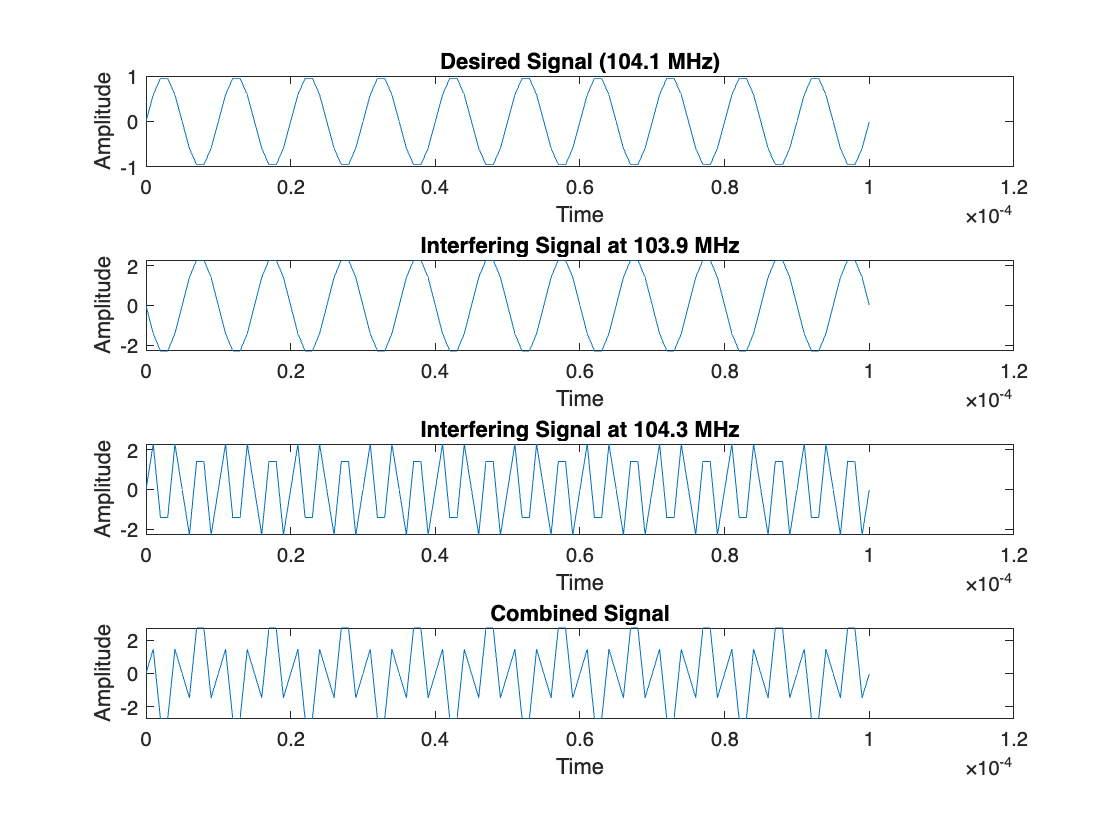


% Plot each sine wave separately
figure;

subplot(4,1,1);
plot(t, desired_signal);
title('Desired Signal (104.1 MHz)');
xlabel('Time');
ylabel('Amplitude');

subplot(4,1,2);
plot(t, interfere_low_scaled);
title('Interfering Signal at 103.9 MHz');
xlabel('Time');
ylabel('Amplitude');

subplot(4,1,3);
plot(t, interfere_high_scaled);
title('Interfering Signal at 104.3 MHz');
xlabel('Time');
ylabel('Amplitude');

subplot(4,1,4);
plot(t, combined_signal);
title('Combined Signal');
xlabel('Time');
ylabel('Amplitude');